# Synthetic Biology - Introduction to mathematical modelling applied to biology

# Code example 1: Mathematical Modelling with Matlab

2024 © Yadira Boada, Alejandro Vignoni

## Simple ODE, exponential growth

### Differential equations with Matlab

We will use the `ode45 `command. Its structure is as follows:

%[t,X] = ode45(@(t,x) model(t,x,params),tspan,x0,options);

where

`t `is the independent variable 

`x` is the dependent variable (or vector of variables) 

`model` is the name of the function giving the differential equation, 

`params` contains parameter values 

`tspan` indicates the time over which the solution is to be obtained, 

`x0` represents the initial conditions, 

`options`  the options of the integrator algorithm.

### Exponential growth 

Recall that the exponential growth equation is given by this expression:


$$$\frac{dx}{dt}=\mu x$$


Go to the end of this document to see the definition of the function.

Next we will use the logistic equation as an example to learn how to obtain the solution (simulate) an ordinary differential equation (model) of interest. We will always have two distinct parts: the function that represents our model and the code needed to run the simulation. We will call the latter the main program.

**Main program**

First we must define the time vector: for this we discretise the time interval in order to find the numerical solutions of this equation for a particular initial condition that will be provided to us. We will discretise the interval [0,20], with a step of 0.2.

%Time (sec)
tfin=20; dt=0.2;
tspan = 0:dt:tfin;

We define the parameters that in this case ($\mu$=1) we are going to pass to the function. And we store them in the vector `params.`

% Parameters:
mu = 1;
params=[mu];

then the initial condiitons:

% Initial conditions
x0=[1];

% Tolerances ode45
options=odeset('RelTol',1e-6,'Stats','off');

Finally, we solve the equation (simulate) with the ode command.

%Call to solver ode45
[t,X] = ode45(@(t,x) model_exp(t,x,params),tspan,x0,options);

Finally, we plot the solution graphically.

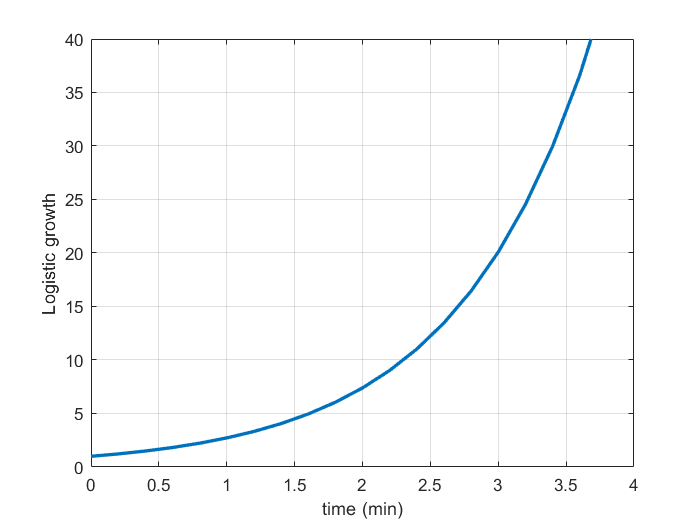

%Plot
figure;
plot(t,X,'LineWidth',2); grid on;
axis([0 4 0 40]);
xlabel('time (min)'); ylabel('Logistic growth');

We change the initial condition to x0 = 12, to check if the solution converges to the same value.

% Initial conditions
x0=[5];

and simulate again:

%Call to solver
[t,X] = ode45(@(t,x) model_exp(t,x,params),tspan,x0,options);

and plot it on the figure above::

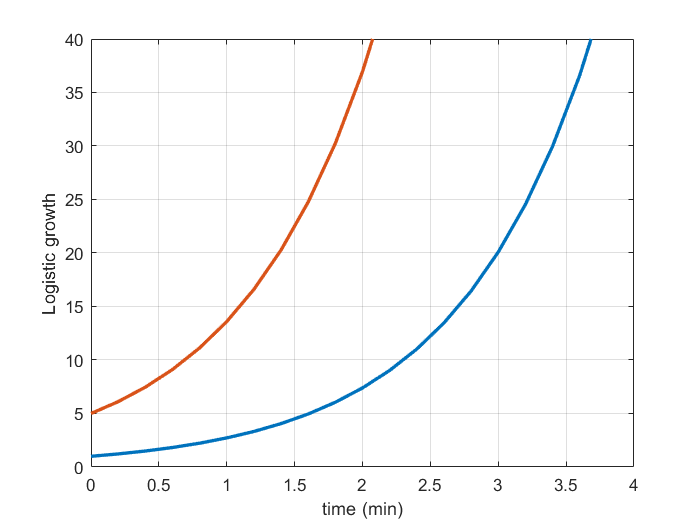

%Plot with hold
hold on
plot(t,X,'LineWidth',2); 

#### Definition of the ODE model/equation as a function

We now define a function that gives us the right-hand term of the differential equation. This expression will be evaluated at an instant $t$ and taking a value $x$, with the `parameters `given. As you can see, you need to pass to the function the following: 

* the value of $t$ where the function is evaluated,

* the value of $x$ where the function is evaluated,

* the parameters that allow us to define the equation.

**ODE Models**

function [dx_dt]= model_exp(t,x,params)
% Model parameters:
mu= params(1);

dx_dt =  mu .* x ;

end